# `OPC Calcium Imaging Analysis`

# `Pre-processing`

cd('C:\Users\97254\OneDrive - mail.tau.ac.il\שולחן העבודה\לימודים\GUI project\data');

## `Import Data`

filename='ROIs_control3_reco1.xlsx'; 
data=readmatrix(filename);
time_vec=data(:,1);
trim=10; %10 sec trim
time_vec=time_vec(trim:end);
dt=time_vec(2)-time_vec(1); %frame rate
data=data(:,3:2:end); %indexing only intensity of each ROI

## `Set Up `

### `Drug Administration`

`In the case of the administration of drugs/substances to the culture during the record, we want to calculate the baseline before the effect of the drug.`

- `Set administration time in line 8`

- `Without administration set to ``X`` (we need to decide)`

admn_time = 120; % time of administration [sec]
admn_time=admn_time+dt-trim;
admn_idx = round(admn_time/dt);

### `Initialization`

n_cells = size(data,2);
num_cells=0;
num_ocillatory_sig=0;
num_LowPlateus_sig=0;
num_HighFlat_sig=0;

baseline_mat=[];
baseline_raw_mat=[];
baseline_corr_mat=[];
baseline_perc_mat=[];
baseline_corrected_data=[];
smooth_cell_data=[];
Sharp_sig = [];
Oscillatory_sig = [];
Neuronal_sig = [];
LowPlateus_sig = [];
HighFlat_sig = [];
Undefined_sig = [];

## `Pre-processing`

### `Terminology`

### `Pre-processing steps`

- `Trimming the first 10 sec of the signals`

- `Baseline correction and expression as (delta F)/F0`

- `Smoothing`

- `Signal Classification `

for cell_num=1:n_cells
    % Trimming first 10 sec of ROIs traces
    cell_RawData=data(trim:end,cell_num); 
       
    % Baseline correction  
    baseline_sig=cell_RawData(1:admn_idx); % signal until drug administration
    baseline_raw_mat(:,end+1)=baseline_sig; % matrix of all baseline signals
    baseline_time=time_vec(1:admn_idx);
    baseline = mean(baseline_sig); % baseline = F0
    baseline_corr_mat(:,end+1) = baseline_sig-baseline;
    baseline_perc_mat(:,end+1) = (baseline_sig-baseline)/baseline;
    cell_data = (cell_RawData-baseline)/baseline; % ΔF/F0
    active_cell_data=cell_data(admn_idx:end,:); % signal after drug administration expresses as (delta F)/F0
    baseline_corrected_data(:,end+1)=cell_data; % matrix of all baseline corrected signals expresses as (delta F)/F0
    
    % smooth the data
    smooth_cell_data(:,end+1) = smooth(cell_data,15);
    smooth_cell_data = smooth(cell_data,15);
    active_smooth_cell_data = smooth(active_cell_data,15);
    
    %% Signal Classification  
    % Oscillations Properties
    normsig = (smooth_cell_data-min(smooth_cell_data))/(max(smooth_cell_data)-min(smooth_cell_data));
    mean_sig = mean(normsig);
    max_sig = max(normsig);
    std_sig = std(normsig);
    std_th = 2;
    
    if mean_sig > 0.38
        std_th = 10;
    end
    
    %Oligo Oscillations
    O_duration_min = 21; %sec
    O_duration_max = 180; %sec
    O_prominence_min = 0.3;
    O_dis_min = 60; %sec
    O_amp_min = max_sig*0.5;
    
    %Neuron Oscillations
    N_duration_min = 5; %sec
    N_duration_max = 21; %sec
    N_prominence_min = 0.4;
    N_amp_min = max_sig*0.5; 
    
    is_peaks=0;
    is_N_peaks=0;
    try
        [O_pks,O_locs,O_w,O_p] = findpeaks(normsig,time_vec,'MinPeakWidth',O_duration_min,'MaxPeakWidth',O_duration_max,'MinPeakProminence',O_prominence_min,'MinPeakHeight',O_amp_min,'MinPeakDistance',O_dis_min);
        [N_pks,N_locs,N_w,N_p] = findpeaks(normsig,time_vec,'MinPeakWidth',N_duration_min,'MaxPeakWidth',N_duration_max,'MinPeakProminence',N_prominence_min,'MinPeakHeight',N_amp_min);
        n_O_pks=length(O_pks);
        n_N_pks=length(N_pks);
        if ~isempty(O_pks)
            if isempty(N_pks)
                is_peaks = 1;
            elseif n_O_pks >= n_N_pks
                is_peaks = 1;
            elseif n_O_pks < n_N_pks
                is_N_peaks = 1;
            end
        else
            if ~isempty(N_pks)
                is_N_peaks = 1;
            end
        end
    %findpeaks(normsig,time_vec_cut,'MinPeakWidth',pic_duration_min,'MaxPeakWidth',pic_duration_max,'MinPeakProminence',pic_Prominence_min,'Annotate','extents','MinPeakHeight',mean_sig+std_sig*std_th,'WidthReference','halfprom');
    catch
        warning('no peks for cell number %d',cell_num)
    end
    
    %Linear Spline interpolation
    inter_points = [admn_idx,admn_idx+30,length(normsig)]; %for glu_inj=60: [40 140 550] %for glu_inj=120: [100 200 850]
    inter_func = interp1(time_vec,normsig,inter_points);
    slope = diff(inter_func)./diff(inter_points);
    
    % neurons 
    if is_N_peaks == 1  
        Neuronal_sig(:,end+1) = smooth_cell_data;
    % multi peak signal 
    elseif is_peaks == 1 
        if mean(active_smooth_cell_data) > 0.1
            Oscillatory_sig(:,end+1) = smooth_cell_data;
        else
            if O_p(1)>=0.5 %|| std(active_smooth_cell_data) > 0.1
                Oscillatory_sig(:,end+1) = smooth_cell_data;
            end
        end
    % Low Plateus Signals
    elseif mean(active_smooth_cell_data) < 0.1
        LowPlateus_sig(:,end+1) = smooth_cell_data;         
    % sharp response signal
    elseif slope(1)>=0.016 %0.033 = raise of 0.5% in 30 sec
        Sharp_sig(:,end+1) = smooth_cell_data;   
    % High Flat Signals
    elseif slope(1)<0.016 && slope(1)>0
        HighFlat_sig(:,end+1) = smooth_cell_data;
    else
        Undefined_sig(:,end+1) = smooth_cell_data; 
    end
    
    num_cells=num_cells+1;

end

## `Visual Assessment`

`Here we plot the signals after classification into 6 catagories:`

- `Oscillatory`

- `Low activity (LowPlateus)`

- `Moderate response (HighFlat)`

- `Suspected as neuronal activity`

- `Undefined activity `

`Then, we visually asses the cllasification - if we suspect a miss clasification, we can manualy correct it.`

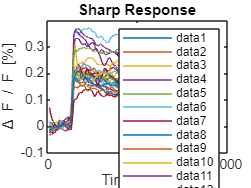

if ~isempty(Sharp_sig)
    figure('Name','Single Peak Signals','Color','white')
    plot(time_vec,Sharp_sig)
    title('Sharp Response')
    xlabel('Time [Sec]');
    ylabel('\Delta F / F [%]');
    legend();
end

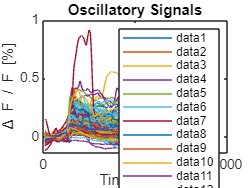


if ~isempty(Oscillatory_sig)
    figure('Name','Multi Peak Signals','Color','white')
    plot(time_vec,Oscillatory_sig)
    title('Oscillatory Signals')
    xlabel('Time [Sec]');
    ylabel('\Delta F / F [%]');
    legend();
end

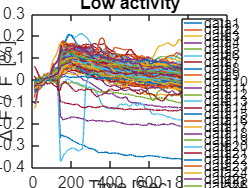


if ~isempty(LowPlateus_sig)
    figure('Name','Flat Signals','Color','white')
    plot(time_vec,LowPlateus_sig)
    title('Low activity')
    xlabel('Time [Sec]');
    ylabel('\Delta F / F [%]');
    legend();
end

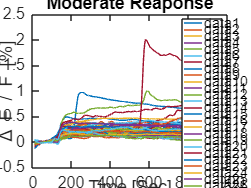


if ~isempty(HighFlat_sig)
    figure('Name','High Flat Signals','Color','white')
    plot(time_vec,HighFlat_sig)
    title('Moderate Reaponse')
    xlabel('Time [Sec]');
    ylabel('\Delta F / F [%]');
    legend();
end

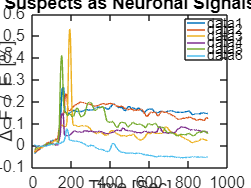


if ~isempty(Undefined_sig)
    figure('Name','Undifained Signals','Color','white')
    plot(time_vec,Undefined_sig)
    title('Undifained Signals')
    xlabel('Time [Sec]');
    ylabel('\Delta F / F [%]');
    legend();
end

if ~isempty(Neuronal_sig)
    figure('Name','Neuronal Signals','Color','white')
    plot(time_vec,Neuronal_sig)
    title('Suspects as Neuronal Signals')
    xlabel('Time [Sec]');
    ylabel('\Delta F / F [%]');
    legend();
end

## `Saving Files`

`After visual asssesment is done and approve, set 'correct' to 1.`

correct =1;

#### `Save structure`

`Dont forget to change back to 0 after saving.`

if correct ==1
    % Final Parametrs
    num_ocillatory_sig=size(Oscillatory_sig,2)+size(Sharp_sig,2);
    num_LowPlateus_sig=size(LowPlateus_sig,2);
    num_HighFlat_sig=size(HighFlat_sig,2);

    % Create data structure
    data_struct.ID = filename;
    data_struct.num_cells = num_ocillatory_sig+num_LowPlateus_sig+num_HighFlat_sig;
    data_struct.perc_ocillatory = (num_ocillatory_sig/num_cells)*100;
    data_struct.perc_LowPlateus = (num_LowPlateus_sig/num_cells)*100;
    data_struct.perc_HighFlat = (num_HighFlat_sig/num_cells)*100;
    data_struct.time_vec = time_vec;
    data_struct.Sharp_sig = Sharp_sig;
    data_struct.Oscillatory_sig = Oscillatory_sig;
    data_struct.LowPlateus = LowPlateus_sig;
    data_struct.HighFlat = HighFlat_sig;
    data_struct.Neurons = Neuronal_sig;
    data_struct.Undefined = Undefined_sig;
    

    save(sprintf('%s.mat',filename), '-struct', 'data_struct');
end